% input_command = importdata("robot_command_modeJ.txt");
% input_command = input_command{1};
% input_via_point = importdata("via_points_info.txt");
% input_via_point = input_via_point{1};
% 
% command = [];
% via_point_task = [];
% input_command = strsplit(input_command);
% input_via_point = strsplit(input_via_point);
% length(input_command)
% for i=1:length(input_command)
%     a = input_command(i);
%     a = a{1};
% %     x = str2double(a(5))
%     if a(2) == 'L'
%         command(i) = 0;
%     elseif a(2) =='J'
%         command(i) = 1;
%     end
%     b = input_via_point(str2double(a(5)));
%     b1 = b{1};
%     text = str2double(strsplit(b1(2:length(b1)-1),','))
% %     temp = [text(1);text(2);text(3)];
%     via_point_task(:,i) = text
% end
% via_point_task

[command, via_point_task_all] = readVariable("robot_command_modeL.txt", "via_points_info.txt");
[alert, via_point_joint] = task2jointConversion(via_point_task_all);


[selected_via_point_joint, all_via_point_joint, cost] = optimalPath(via_point_joint, "shortest_path");

min_cost = 4.8976

min_idx = 1365

v_max = 1.75;
a_max = 0.5;
[C,t_i,T,alert_traj] = coefficientGen(selected_via_point_joint, v_max, a_max)

C = C(:,:,1) =

         0         0         0         0         0         0
         0         0         0   -0.3888    0.2618   -0.0470
         0         0         0   -0.3888    0.2618   -0.0470


C(:,:,2) =

         0         0         0    0.1461   -0.0581    0.0062
   -0.4298         0         0   -0.0389    0.0155   -0.0016
   -0.4298         0         0    0.2295   -0.0912    0.0097


C(:,:,3) =

    0.7854         0         0   -0.2033    0.0716   -0.0067
   -0.6388         0         0         0         0         0
    0.8038         0         0         0         0         0


C(:,:,4) =

   -0.7854         0         0    0.1461   -0.0581    0.0062
   -0.6388         0         0    0.0389   -0.0155    0.0016
    0.8038         0         0   -0.2295    0.0912   -0.0097


C(:,:,5) =

         0         0         0         0         0         0
   -0.4298         0         0    0.3888   -0.2618    0.0470
   -0.4298         0         0    0.3888   -0.2618    0.0470


t_i =          0    2.2277    6.0019   10.2607   14.0349


T = 16.2626

alert_traj = 0

[C_t,t_i,T] = coefficientGenTask(via_point_task_all,t_i,T)

C_t = C_t(:,:,1) =

    0.3500         0         0         0         0         0
         0         0         0         0         0         0
    0.3500         0         0   -0.2261    0.1523   -0.0273


C_t(:,:,2) =

    0.3500         0         0         0         0         0
         0         0         0    0.0651   -0.0259    0.0027
    0.1000         0         0    0.0465   -0.0185    0.0020


C_t(:,:,3) =

    0.3500         0         0         0         0         0
    0.3500         0         0   -0.0906    0.0319   -0.0030
    0.3500         0         0         0         0         0


C_t(:,:,4) =

    0.3500         0         0         0         0         0
   -0.3500         0         0    0.0651   -0.0259    0.0027
    0.3500         0         0   -0.0465    0.0185   -0.0020


C_t(:,:,5) =

    0.3500         0         0         0         0         0
         0         0         0         0         0         0
    0.1000         0         0    0.2261   -0.1523    0.0273


t_i =          0    2.2277    6.0019   10.2607   14.0349


T = 16.2626

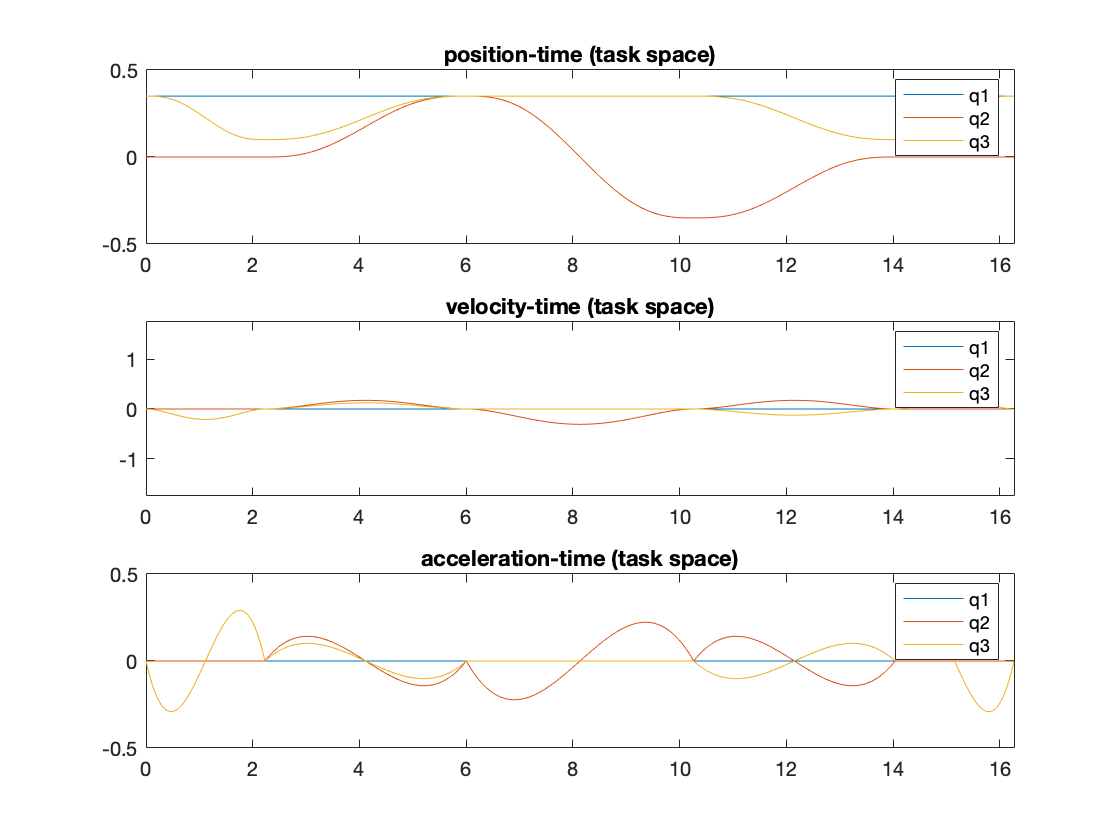

sampling = 1e-2; t = (0:sampling:T); %linspace(0,T,100+1);
p = [];
v = [];
a = [];

for i = 1:numel(t)
    k = discretize(t(i),[t_i T]);
   [p_j,v_j,a_j] = polyTrajEval(t(i),C_t(:,:,k),t_i(k));

    p = [p p_j];
    v = [v v_j];
    a = [a a_j];

end

subplot(3,1,1)
plot(t, p)
title('position-time (task space)')
legend({'q1','q2','q3'})
xlim([0 T])

subplot(3,1,2)
plot(t, v)
title('velocity-time (task space)')
legend({'q1','q2','q3'})
xlim([0 T]); ylim([-v_max v_max])

subplot(3,1,3)
plot(t, a)
title('acceleration-time (task space)')
legend({'q1','q2','q3'})
xlim([0 T]); ylim([-a_max a_max])
hold off;

[flag, p3] = task2jointConversion([-0.248004406180352;
0;
0.562132000000000])

flag = 1

p3 =     3.1416    3.1416    3.1416    3.1416
   -0.8646    0.0550   -0.8646    0.0550
    2.4094    0.7322    2.4094    0.7322


q3 = chooseQ([0.596202000000000;0;0.143412000000000],[0;0;0])

q3 =          0
   -1.3963
    1.3963


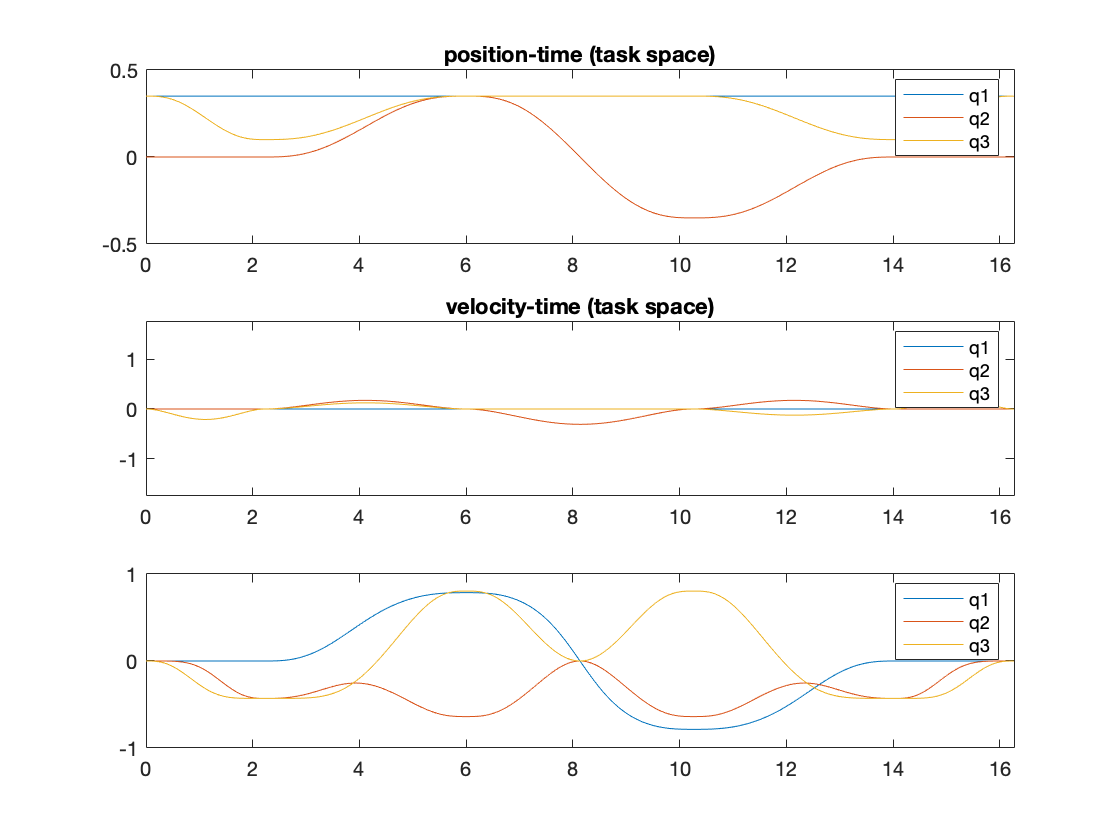


p = [];
v = [];
a = [];
q = [];
q_temp = selected_via_point_joint;
for i = 1:numel(t)
    k = discretize(t(i),[t_i T]);
    [p_j,v_j,a_j] = polyTrajEval(t(i),C_t(:,:,k),t_i(k));
    if k == 1
        [q_t,alert] = chooseQ(p_j,q_temp(:,k));
    else
        [q_t,alert] = chooseQ(p_j,q_temp(:,k+1));
    end
    if alert == 1
        break
    end
    p = [p p_j];
    v = [v v_j];
    a = [a a_j];
    q = [q q_t];
end
plot(t,q)
legend({'q1','q2','q3'})
xlim([0 T]);
hold off;